## Test for EMG electrodes through Arduino connection

Close all ports and clear workspace?

try
    uno.close;
catch
end
clear all; clc;

## Section 1: Set Up Virtual Environment (MuJoCo)

You should have MuJoCo open with a model loaded and running before starting this code! If your code is crashing during this section, try the following: 

- Close MuJoCo

- Open MuJoCo

- Open Model

- Play MuJoCo

- Run MATLAB Code

[model_info, movements, command, selectedDigits_Set1, selectedDigits_Set2, VREconnected] = connect_hand;

VRE failed to connect. :(


## Connect to arduino

[uno, ArduinoConnected]=connect_ard1ch();% can put the comport number in as an argument to bypass automatic connection, useful if more than one arduino uno is connected

Arduino connected! :)


## Plot (and control) in real time

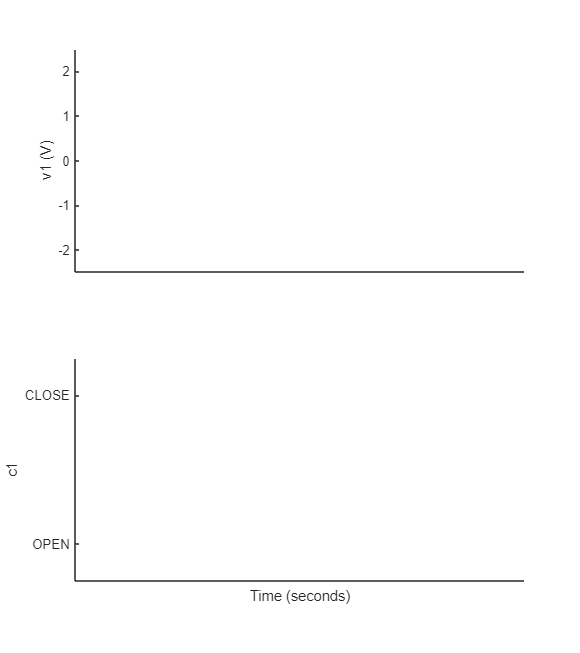

% SET UP PLOT
[fig, animatedLines, Tmax, Tmin] = plotSetup1ch();


% INITIALIZATION
[data, control, data_idx, control_idx, prev_samp, prev_timestamp] = init1ch();
tdata=[0];
tcontrol=[];
pause(0.5)
tic
while(ishandle(fig)) %run until time is out or figure closes
    % SAMPLE ARDUINO
    try
        emg = uno.getRecentEMG;% values returned will be between -2.5 and 2.5 , will be a 1 x up to 330
        if ~isempty(emg)
            [~,newsamps] = size(emg); % helps to know how much more data was received
            data(:,dataindex:dataindex+newsamps-1) = emg(1,:); % adds new EMG data to the data vector
            dataindex = dataindex + newsamps; %update sample count
            controlindex = controlindex + 1;
        end
    catch
    end
    if ~isempty(emg)
        % UPDATE
        timeStamp = toc; %get timestamp
        % CALCULATE CONTROL VALUES
        try

## start of your code

            control(1,controlindex) = emg(1,end);

## end of your code

        catch
            disp('Something broke in your code!')
        end
        tcontrol(controlindex)=timeStamp;
        tempStart = tdata(end);
        tdata(prev_samp:dataindex-1)=linspace(tempStart,timeStamp,newsamps);
        % UPDATE PLOT
        [Tmax, Tmin] = updatePlot1ch(animatedLines, timeStamp, data, control, prev_samp, dataindex, controlindex, Tmax, Tmin);
        
        % UPDATE HAND
        if(VREconnected) %if connected
            status = updateHand(control, controlindex, command, selectedDigits_Set1, selectedDigits_Set2);
        end
        prev_timestamp = timeStamp;
        prev_samp = dataindex;
    end
end

Something broke in your code!


Unrecognized function or variable 'controlindex'.

## Plot the data and control values from the most recent time running the system

finalPlot(data,control,tdata,tcontrol)

## close the arduino serial connection before closing MATLAB

uno.close;